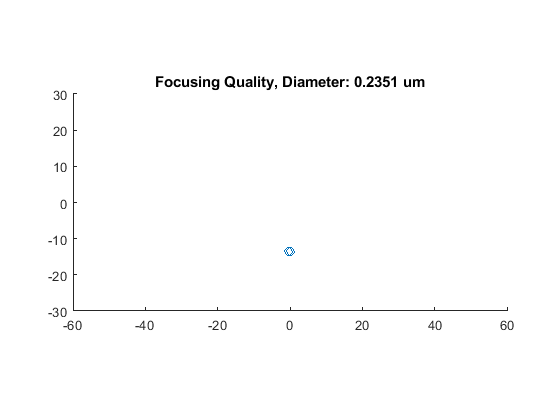

% dpm viewer

step = 75;
width = 120;
re = 41;
filewildcard = sprintf('dpm_data_cw%d_ch%d_cl500_nh%d_nl%d_q*_re%d_step%d.dpm', width, width/2, width/4, width/2, re, step);

folder = './dpm/';
d = dir([folder, filewildcard]);
filename = [d(1).folder '\' d(1).name];
prevstepfilename = [filename(1:end-(4+ceil(log10(step)))), num2str(step-1), '.dpm'];

data = importdpm(filename);
% dataprev = importdpm(prevstepfilename);

figure; hold on;

% for i = 1:size(dataprev,1)
%     plot([data.z(i), dataprev.z(i)]*1e6, [data.y(i), dataprev.y(i)]*1e6, 'r', 'HandleVisibility', 'off');
% end

plot(data.z*1e6, data.y*1e6, 'o');
axis equal
xlim([-width/2, width/2]);
ylim([-width/4, width/4]);

title(sprintf('Focusing Quality, Diameter: %.4f um', sqrt(std(data.z*1e6).^2 + std(data.y*1e6).^2)))